### Enrico Giannobile 19.00610-0

#### Boas práticas

clear all;
close all;
clc;

#### Leitura inicial dos arquivos individuais das vogais + Criação de um .mat com os dados lidos


% 
% a = cell(1,5); % prealocando
% a{1,5} = [];
% 
% 
% e = cell(1,5); % prealocando
% e{1,5} = [];
% 
% 
% i = cell(1,5); % prealocando
% i{1,5} = [];
% 
% 
% o = cell(1,5); % prealocando
% o{1,5} = [];
% 
% 
% u = cell(1,5); % prealocando
% u{1,5} = [];
% 
% for ii = 1:5
% %%%% Leitura da vogal a
%     File = "a" + ii + ".wav";
%     
%     [Y,FS] = audioread(File);
%     
%     a{:,ii} = Y;
%     
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal e
%     File = "e" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
%     
% 
%     e{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal i
%     File = "i" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
% 
%     i{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal o
%     File = "o" + ii + ".wav";
% 
%     [Y,FS] = audioread(File);
% 
%     o{:,ii} = Y;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%% Leitura da vogal u
%     File = "u" + ii + ".wav";
%     
%     [Y,FS] = audioread(File);
% 
%     u{:,ii} = Y;
% 
% end
% save('Vogais.mat', 'a', 'e', 'i', 'o', 'u');


 

#### Carregando .mat e plotando gráficos das vogais no domínio do tempo e frequência

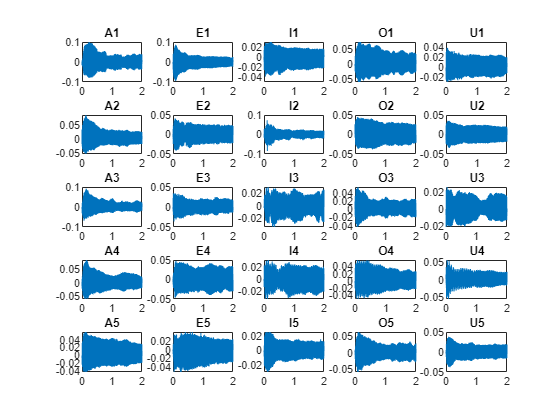

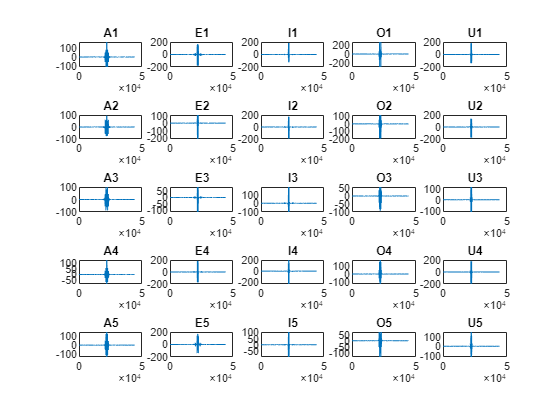

%% Prealocando
a = cell(1,5);
e = cell(1,5); 
i = cell(1,5); 
o = cell(1,5); 
u = cell(1,5);
%% 


load('Vogais.mat')   % Carregando o arquivo .mat

FS = 44100;          % Frequência

j = 0;



for n = 1:5

    Y = a{:,n};

    N       = length(Y);               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    j = j + 1;

%% Primeiro Plot ( gráficos em função do tempo )
    figure(1);
    subplot(5,5,j);
    
    
    plot(tempo,Y);
    title("A" + n);

%% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);
    subplot(5,5,j);

    plot(freq,fftshift(fft(Y)));
    title("A" + n);
%----------------------------------------
    Y = e{:,n};

    N       = length(Y);               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    j = j + 1;
    
%% Primeiro Plot ( gráficos em função do tempo )
    figure(1);
    subplot(5,5,j);
    
    
    plot(tempo,Y);
    title("E" + n);

%% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);
    subplot(5,5,j);

    plot(freq,fftshift(fft(Y)));
    title("E" + n);
%----------------------------------------
    Y = i{:,n};

    N       = length(Y);               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    j = j + 1;
    

%% Primeiro Plot ( gráficos em função do tempo )
    figure(1);
    subplot(5,5,j);
    
    
    plot(tempo,Y);
    title("I" + n);

%% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);
    subplot(5,5,j);

    plot(freq,fftshift(fft(Y)));
    title("I" + n);
%----------------------------------------
    Y = o{:,n};

    N       = length(Y);               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    j = j + 1;
    
%% Primeiro Plot ( gráficos em função do tempo )
    figure(1);
    subplot(5,5,j);
    
    
    plot(tempo,Y);
    title("O" + n);

%% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);
    subplot(5,5,j);

    plot(freq,fftshift(fft(Y)));
    title("O" + n);
%----------------------------------------
    Y = u{:,n};

    N       = length(Y);               
    Ts      = 1/FS;                     
    ws      = 2*pi*FS;                
    duracao = N*Ts;                    
    tempo   = linspace(0,duracao,N);   
    fmax    = FS/2;
    j = j + 1;

%% Primeiro Plot ( gráficos em função do tempo )
    figure(1);
    subplot(5,5,j);
    
    
    plot(tempo,Y);
    title("U" + n);

%% Segundo Plot ( gráficos em função da frequência )
    freq = linspace(0,FS,N);

    figure(2);
    subplot(5,5,j);

    plot(freq,fftshift(fft(Y)));
    title("U" + n);
end